

for i = 2:253
 DIA.Rocclose(i)=((DIA.close(i)-DIA.close(i-1))/DIA.close(i-1))*100;
end   


for i = 1:253
 DIA.Diffopenclose(i)=((DIA.open(i)-DIA.close(i))/DIA.open(i))*100;    
end

for i = 1:253
 DIA.DiffHighlow(i)=((DIA.high(i)-DIA.low(i))/DIA.low(i))*100;    
end


DIA.movavergopen=movaverg(DIA.open)



DIA.Diffopen=Diff(DIA.open,DIA.movavergopen);




DIA.movaverghigh=movaverg(DIA.high);
DIA.Diffhigh=Diff(DIA.open,DIA.movaverghigh);


DIA.movaverglow=movaverg(DIA.low);;

DIA.Difflow=Diff(DIA.open,DIA.movaverglow);

DIA.movavergclose=movaverg(DIA.close);

DIA.Diffclose=Diff(DIA.open,DIA.movavergclose);

DIA.movavergvolume=movaverg(DIA.volume);

DIA.Diffvolume=Diff(DIA.volume,DIA.movavergvolume);

%S&P preprocessing 
SP.movaverghigh=movaverg(SP.High);
SP.Diffhigh=Diff(SP.High,SP.movaverghigh);
DIA.sp=scale11(SP.Diffhigh);

%Dax preprocessimg

DIA.daxopen=scale11(dax.Open);

%nasdaq preprocessing
nasdaq.movavergopen=movaverg(nasdaq.open);
nasdaq.Diffopen=Diff(nasdaq.open,nasdaq.movavergopen);

DIA.nasdaq=scale11(nasdaq.Diffopen);

%preprocessing dow jon indu
dowjonesindu.movaverglow=movaverg(dowjonesindu.Low);

dowjonesindu.Difflow=Diff(dowjonesindu.Low,dowjonesindu.movaverglow);

DIA.dowjonesindu=scale11(dowjonesindu.Difflow);

%preprocessing dowjonestrans
dowjonestrans.movavergclose=movaverg(dowjonestrans.Close);
dowjonestrans.Diffclose=Diff(dowjonestrans.Close,dowjonestrans.movavergclose);
DIA.dowjonestrans=scale11(dowjonestrans.Diffclose);

%final scaling

DIA.open=scale11(DIA.open);
DIA.Diffopenclose=scale11(DIA.Diffopenclose);
DIA.DiffHighlow=scale11 (DIA.DiffHighlow);
DIA.Diffopen(11:253)=scale11(DIA.Diffopen(11:253));
DIA.Diffhigh(11:253)=scale11(DIA.Diffhigh(11:253));
DIA.Difflow(11:253)= scale11(DIA.Difflow(11:253));
DIA.Diffvolume(11:253)=scale11(DIA.Diffvolume(11:253));
DIA.Diffclose(11:253)=scale11(DIA.Diffclose(11:253));
DIA.Diffhigh(11:253)=scale11(DIA.Diffhigh(11:253));
DIA.close=scale11(DIA.close);



% 
% t=1:253;
% plot(t,DIA.Rocclose);
% plot(t,DIA.Diffopenclose);

%creation de la population  et determination du vecteur de forcating
N=45;
pop=init(10);
popcro=init(2); forr=forcast(N,popcro,DIA);er=error1(forr,N,popcro,DIA);

forcasted=forcast(N,pop,DIA)

forcasted =     0.4039    0.0325    0.2330    0.9618    0.0373    0.9695    0.2078    0.0190    0.0102    0.7679
    0.4047    0.0320    0.2247    0.9621    0.0374    0.9040    0.2087    0.0191    0.0106    0.3178
    0.4114    0.0318    0.2246    0.9622    0.0422    0.9031    0.2080    0.0191    0.0106    0.3228
    0.4246    0.0307    0.2248    0.9629    0.0451    0.9301    0.2029    0.0188    0.0106    0.5323
    0.4535    0.0276    0.2181    0.9663    0.0452    0.9607    0.2292    0.0188    0.0103    0.7672
    0.4546    0.0289    0.2204    0.9656    0.0404    0.9634    0.2212    0.0188    0.0103    0.7768
    0.4259    0.0307    0.2244    0.9630    0.0371    0.9601    0.2050    0.0188    0.0105    0.6089
    0.5980    0.0045    0.2368    0.9775    0.4992    0.9563    0.3486    0.0171    0.0043    0.8216
    0.4622    0.0144    0.1897    0.9721    0.0642    0.8645    0.4039    0.0174    0.0099    0.7126
    0.4646    0.0280    0.2169    0.9622    0.0424    0.9040    0.3533    0.017

err=error1(forcasted,N,pop,DIA)

err =     6.6680
   24.8874
   14.5086
    0.3855
   22.6374
    0.2922
   14.3656
   25.4795
   25.9774
    3.5766


pop=order(pop);
pop(:).erreur

ans = 0.2922

ans = 0.3855

ans = 3.5766

ans = 6.6680

ans = 14.3656

ans = 14.5086

ans = 22.6374

ans = 24.8874

ans = 25.4795

ans = 25.9774

pop(7).erreur

ans = 22.6374


while pop(1).erreur>0.05
%     pop=mutation(5,45,DIA,pop);
    pop=crossover1(pop,popcro);
    disp('dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk')
    disp(pop(1).erreur)
    
end

dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.2922



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.2922



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.2922



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.1970



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.1970



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.1970



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.1970



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.1087



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.1087



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.1087



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0858



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0858



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0858



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0858



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0858



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0858



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0858



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0858



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0858



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0629



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0629



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0629



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0629



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0617



new
niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0783



niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


new
niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0783



niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


new
niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0783



niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


new
niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0783



niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


new
niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0783



niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


new
niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0783



niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


new
niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0783



niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


new
niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0783



niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


new
niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0783



niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


new
niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0783



niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


new
niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0783



niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


new
niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0783



niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


new
niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0783



niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


new
niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0783



niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


new
niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0783



niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


new
niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0783



niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


new
niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0783



niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


new
niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0783



niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


new
niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0783



niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


new
niveau2
  Columns 1 through 12

   -2.3789   -4.1424   -0.4617    4.8231    3.8430    2.6989    1.7120    4.7142   -0.9963    3.0154    0.5792   -3.7433

  Columns 13 through 16

    4.2741    0.5518    1.7479    2.3109

niveau3
   -2.5721    4.6840   -0.5288   -2.4475



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0783



niveau2
  Columns 1 through 12

   -0.7992    2.5780   -1.0505    2.6394   -4.5613   -2.4416    0.3423   -1.4603   -4.8023   -0.4194    1.2968   -0.9664

  Columns 13 through 16

   -4.0264   -1.8597    1.1570   -1.3980

niveau3
    2.3074   -0.0035   -4.1145    4.7092



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


new
niveau2
  Columns 1 through 12

   -0.7992    2.5780   -1.0505    2.6394   -4.5613   -2.4416    0.3423   -1.4603   -4.8023   -0.4194    1.2968   -0.9664

  Columns 13 through 16

   -4.0264   -1.8597    1.1570   -1.3980

niveau3
    2.3074   -0.0035   -4.1145    4.7092



ans =   layer with properties:

    nombredeneurone: 1
           Listneur: [1×1 neurone]


dkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkkk


    0.0465



pop(:).erreur

ans = 0.3119

ans = 0.3751

ans = 0.5682

ans = 0.5875

ans = 0.6466

ans = 1.2545

ans = 7.6688

ans = 7.7752

ans = 15.9250

ans = 22.0213

forcasted=forcast(N,pop,DIA)

forcasted =     0.9550    0.9785    0.9879    0.9708    0.9989    0.8380    0.3940    0.3960    0.0889    0.0067
    0.9533    0.9699    0.9939    0.9990    0.9989    0.7514    0.4673    0.3782    0.0540    0.0548
    0.9538    0.9671    0.9941    0.9992    0.9989    0.7027    0.4438    0.3779    0.0590    0.0794
    0.9554    0.9757    0.9931    0.9992    0.9989    0.6432    0.3792    0.3824    0.1912    0.0796
    0.9558    0.9767    0.9816    0.9991    0.9989    0.5820    0.3899    0.4128    0.3916    0.0333
    0.9556    0.9764    0.9808    0.9990    0.9989    0.6086    0.3879    0.3966    0.3598    0.0277
    0.9553    0.9785    0.9884    0.9982    0.9989    0.7056    0.4169    0.3934    0.1769    0.0164
    0.9529    0.9765    0.9927    0.9974    0.9989    0.8019    0.4764    0.4561    0.2632    0.1244
    0.9593    0.9829    0.9771    0.9990    0.9989    0.6403    0.3379    0.5654    0.4538    0.0326
    0.9556    0.9785    0.9810    0.9988    0.9989    0.6213    0.3980    0.381

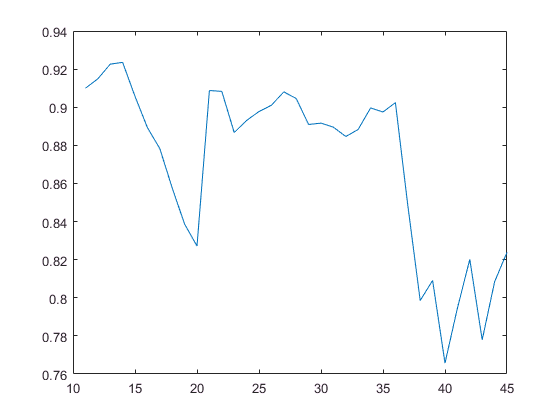

plot(s,DIA.close(11:N))

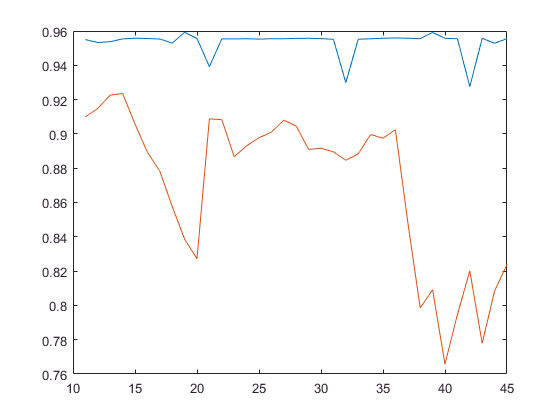

plot(s,forcasted(:,1),s,DIA.close(11:N))

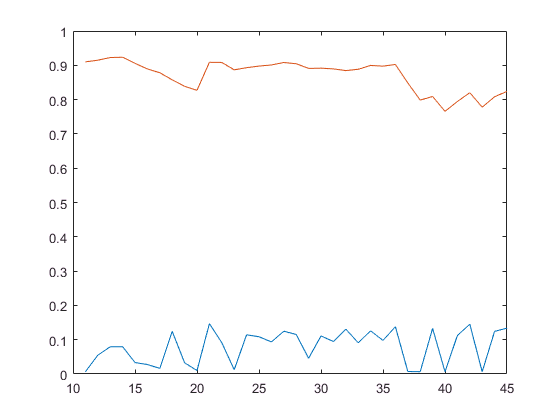

plot(s,forcasted(:,10),s,DIA.close(11:N))

pop(:).erreur

dre=init(1)
dre(1).crossover(pop(1))
fo=forcast(N,dre,DIA)
err=error1(fo,N,dre,DIA)

 pop(1).erreur
% forcasted=forcast(N,pop,DIA)

s=11:N
pop=order(pop)
pop(:).erreur
err=error1(forcasted,N,pop,DIA)
plot(s,DIA.close(11:N))
plot(s,forcasted(:,1),s,DIA.close(11:N))
plot(s,forcasted(:,7),s,DIA.close(11:N))

plot(s,forcasted(:,5),s,DIA.close(11:N))

oo=init(2)
oo(1).affiche();


